% Connect to sensor and run this

% Uncomment following 3 lines for sensor input
% ElikoReconnect();
% output = ElikoSample();
% PicometerControl('Disconnect');

% real1 = real(output(:,1));
% imag1 = imag(output(:,1));
% 
% plot(real1,imag1,'g*');

output = complex(rand(99, 15) * 100, rand(99, 15) * 100)

output =   85.0840 +69.9166i   4.2899 +57.7042i  73.2250 +68.6802i  22.5238 + 0.8155i  78.4307 +26.7371i  73.3390 +57.4603i  73.7276 +75.7794i  91.0426 +67.2689i  18.0407 +46.5090i   6.2143 +50.9384i  43.1772 +42.5634i  23.3507 +64.1959i   5.0032 +63.8945i  23.6012 +13.8443i  66.3977 +62.4324i
  63.2508 +42.0061i  76.8962 +77.5813i  34.4985 +19.9843i  23.4836 +69.3153i  42.6729 +93.6907i   0.3588 +89.5184i  33.0565 +27.9735i   1.1148 +52.8225i  49.6784 +60.5343i  16.4976 +87.2752i  80.4785 +20.4596i  97.0552 +90.2312i  67.5037 +37.3497i  33.0421 +65.7780i  64.4196 +82.2578i
  47.8329 +78.6578i  26.7065 +83.2422i  11.4524 +97.1360i  37.4961 +14.5478i  28.9993 +32.4160i  89.1238 +17.3911i  31.3943 +56.7616i  77.1288 + 4.1761i  20.1096 +56.2655i  86.6773 +75.2642i  39.4986 +30.4831i   4.3070 +75.7016i  93.5262 +66.7845i  13.2401 +74.2300i  42.3037 +61.1769i
  66.4430 +26.8535i  41.3578 +16.4197i  52.5612 +11.7559i  75.6648 +34.1839i  85.5082 +82.4605i  22.5505 + 2.4692i  77.5455 +24.0105i

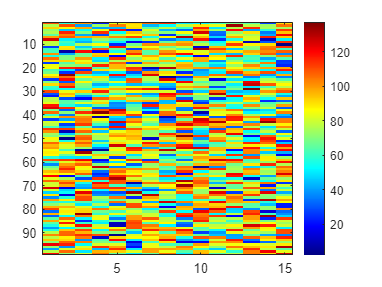


% Compute the magnitudes of each number in the matrix
magnitude_matrix = abs(output);

% Plot the magnitude matrix as image or heatmap
imagesc(magnitude_matrix);
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

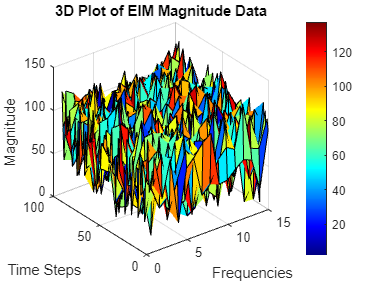


% Assuming magnitude_matrix contains your magnitude data
figure;
surf(magnitude_matrix);

% Customize the plot appearance
title('3D Plot of EIM Magnitude Data');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

% Define a threshold to identify noise
percentage_threshold = 90;

% Assuming magnitude_matrix contains your magnitude data
filtered_magnitude_matrix = magnitude_matrix;  % Initialize with the original data

% Define the sampling frequency (adjust as needed)
sampling_frequency = 1500.0;  % Change this to your actual sampling frequency

% Define the cutoff frequency for the high-pass filter
cutoff_frequency_hz = 2000;  % 2 kHz

% Calculate the passband frequency as half of the cutoff frequency
passband_frequency_hz = 1.1* cutoff_frequency_hz;

% Normalize the frequencies for filter design
sampling_frequency = 1500.0;  % Change this to your actual sampling frequency
normalized_cutoff_frequency = cutoff_frequency_hz / (0.5 * sampling_frequency);
normalized_passband_frequency = passband_frequency_hz / (0.5 * sampling_frequency);

% Design the high-pass filter
filter_order = 4;  % Adjust as needed

% Ensure that normalized_passband_frequency and normalized_cutoff_frequency are in the (0, 0.5) interval
if normalized_passband_frequency >= 0.5 || normalized_cutoff_frequency >= 0.5
    error('Frequency specifications for high-pass filter must be between 0 and 0.5.');
end

Frequency specifications for high-pass filter must be between 0 and 0.5.


highpass_filter = designfilt('highpassfir', ...
    'PassbandFrequency', normalized_passband_frequency, ...
    'StopbandFrequency', normalized_cutoff_frequency, ...
    'FilterOrder', filter_order);

% Apply the high-pass filter to your data
filtered_magnitude_matrix = filter(highpass_filter, filtered_magnitude_matrix);

% Apply thresholding to remove values above the threshold
threshold_value = prctile(filtered_magnitude_matrix(:), percentage_threshold);
filtered_magnitude_matrix(filtered_magnitude_matrix > threshold_value) = NaN;

% Assuming filtered_magnitude_matrix contains the filtered signal data
figure;
imagesc(filtered_magnitude_matrix);
colormap('jet');
colorbar;

% Customize the plot appearance
title('Filtered EIM Magnitude Data');
xlabel('Frequencies');
ylabel('Time Steps');

% Assuming filtered_magnitude_matrix contains the filtered signal data
figure;
surf(filtered_magnitude_matrix);

% Customize the plot appearance
title('3D Plot of Filtered EIM Magnitude Data');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference